# Лабораторная работа №3

Численное интегрирование, метод трапеций.

f = @(x) x.^2;
d = [-1, 1];
get_int_trap(f, d, 10)

ans = 0.6831

integral(f, -1, 1)

ans = 0.6667

Построение зависимости от количества точек

Зависимость от параметра!

Вывод функции.

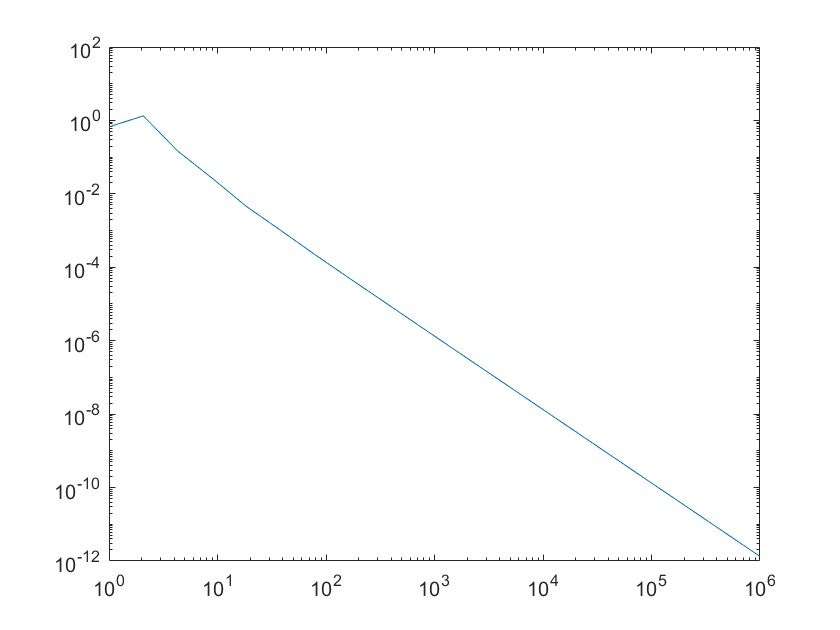

n = logspace(0, 6, 20);
f = @(x) x.^2;
E = [];
d = [-1, 1];
for i = 1:max(size(n))
    eps = abs(get_int_trap(f, d, n(i)) - integral(f, d(1), d(2)));
    E = [E eps];
end
loglog(n, E);

function s = get_int_trap(f, d, n)
   X = linspace(d(1), d(2), n);
   s = 0;
   parfor i = 2:max(size(X))
       s = s + trap(f, X(i-1), X(i));
   end
end

function i = trap(f, a, b)
    i = (b - a)/2*(f(a) + f(b));
end